# Polinomios de interpolación en el análisis de temperatura

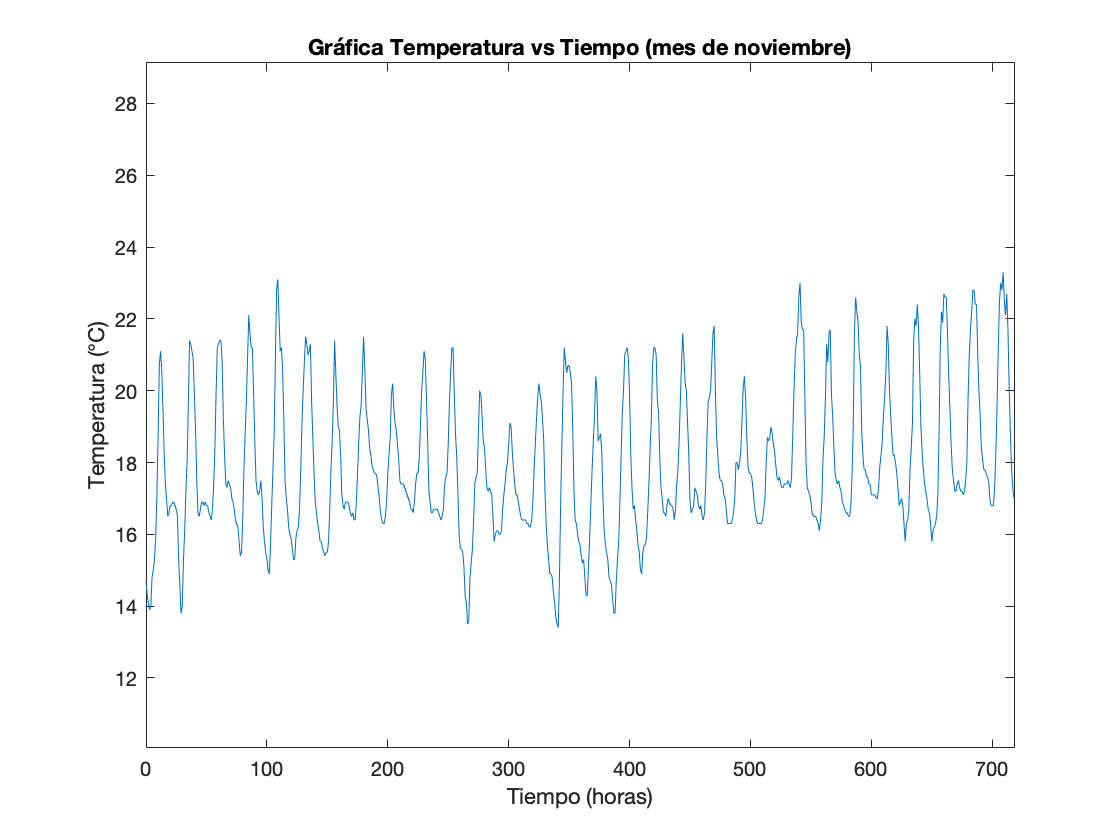

TNov = readmatrix('data.csv','Range','C12:C730')';
tNov = (0:1:length(TNov)-1);
GraficaGeneral(TNov, tNov); hold off;

opcion = input('¿Usted tiene conocimiento del proyecto? Sí/No: ', 's');

if strcmp(opcion, 'Sí')
    hora = input("Ingresa la hora del día a analizar (0-23): ");
    grado = input("Ingresa el grado del polinomio aproximante: ");
else
    hora = 12;
    grado = 1;
    fprintf('Hora por defecto: %d\n', hora)
    fprintf('Grado de polinomio de mínimos cuadrados por defecto: %d\n', grado)
end

[tNovHora, TNovHora, Sx, P] = GraficaSpline(TNov, hora+1, grado);
hold off

Spline Cúbico Natural:

## 
$$S_i \left(x\right)={a\left(x-x_i \right)}^3 +{b\left(x-x_i \right)}^2 +c\left(x-x_i \right)+d\;\;\;\;\forall \;\;\;\;i=0,1,\ldotp \ldotp \ldotp ,N-1$$


disp(Sx)

Graficamos el polinomio interpolante de Newton:

GraficaNewton(tNovHora, TNovHora, ceil(length(tNovHora)/2));

Gráfica de aproximación para los primeros días de diciembre:

TDic = readmatrix('diciembre.csv','Range','C12:C263')';
TDicHora = TDic((hora+1):24:end);
[~, n] = size(TDicHora);

fprintf("Cantidad de Temperaturas reales de diciembre disponibles: %d", n)

Cantidad de Temperaturas reales de diciembre disponibles: 10

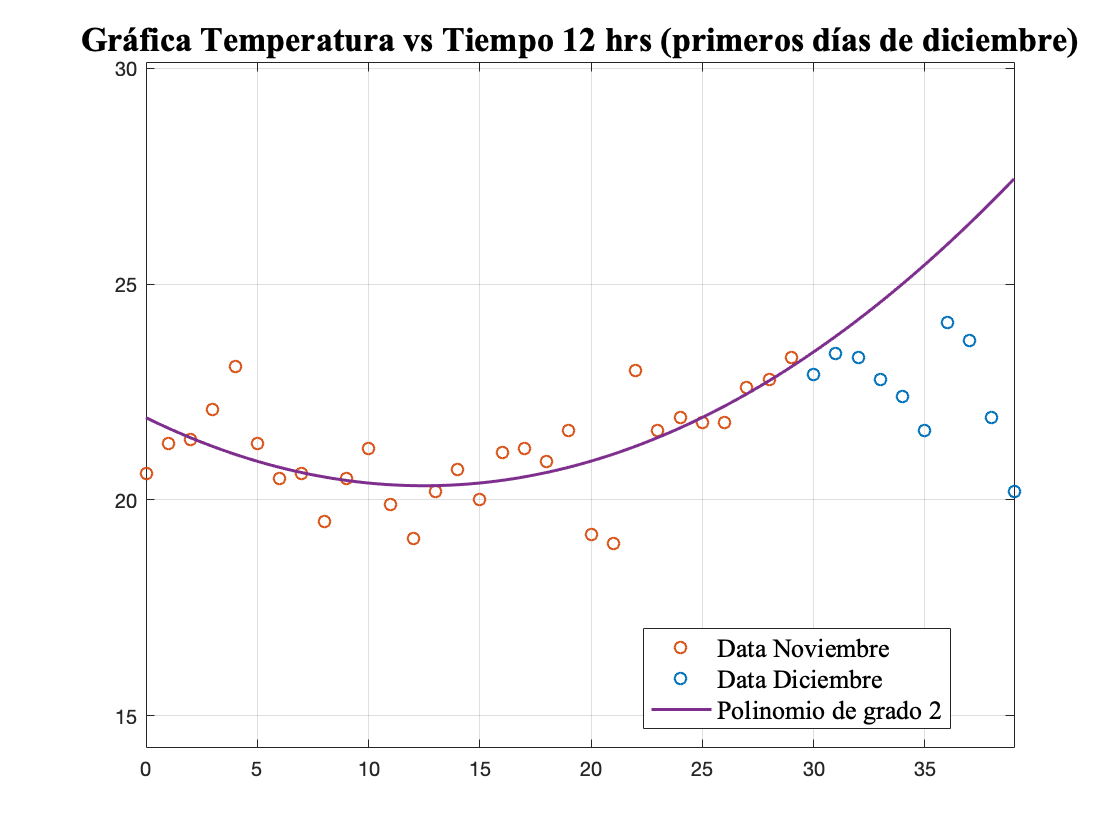

while true
    dias = input('Ingrese la cantidad de días de diciembre para estimar: ');
    if dias <= n
        break
    end
end

GraficaConDiciembre(TNovHora, TDicHora(1, 1:dias), hora, P, grado, dias);

Taprox = polyval(P, (31:1:(30+dias)));
Treal = TDicHora(1:dias);

Error_abs = abs(Treal - Taprox);
disp("Error absoluto de las aproximaciones realizadas para el mes de Diciembre en orden diario"); disp(Error_abs);

Error absoluto de las aproximaciones realizadas para el mes de Diciembre en orden diario
    0.8946    0.7793    1.2842    2.2093    3.0546    4.3202    2.3060    3.2121    5.5383    7.7848



Error_relativo = Error_abs./Treal;
disp("Error relativo de las aproximaciones realizadas para el mes de Diciembre en orden diario"); disp(Error_relativo);

Error relativo de las aproximaciones realizadas para el mes de Diciembre en orden diario
    0.0391    0.0333    0.0551    0.0969    0.1364    0.2000    0.0957    0.1355    0.2529    0.3854

